# Sessio 8

**Yaiza Cano, Narcís Terrado**

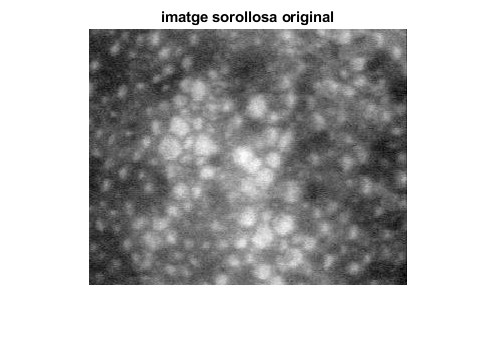

%obrim la imatge
orig = imread('cornea.tif');
figure, imshow(orig); title('imatge sorollosa original')

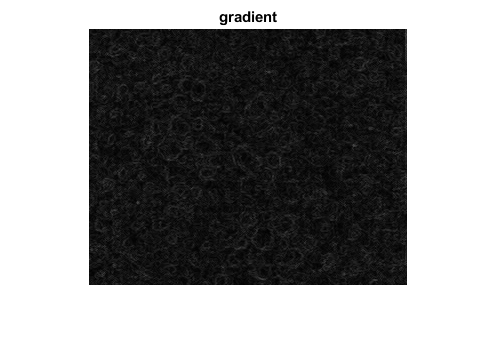


%calculem el gradient
ee = strel('disk',1);
grad = imsubtract(imdilate(orig,ee), imerode(orig,ee));
figure, imshow(grad), title('gradient');

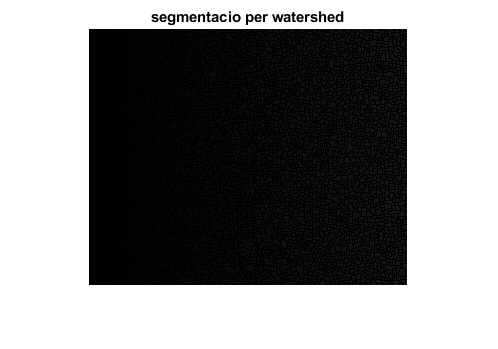


%segmentem la imatge amb watershed
segm = watershed(grad);
figure, imshow(segm), title('segmentacio per watershed')

Com hem vist en la sessió anterior, no podem segmentar la imatge utilitzant el gradient, necessitem treballar markers.